# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Metoda Gausa-Seidla

**ĆWICZENIE 1tOr**

Poniżej przedstawiono implementację zwykłą metody Gaussa-Seidla. Zwróć uwaę jak metoda korzsyta z nowo obliczonych wartości:

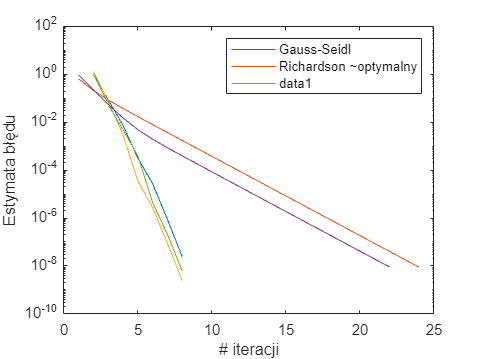

%Czyszczenie
clear all;clc;

% Najpierw zdefiniujmy przykładowy układ równań:
A=wilkinson(5)+10*eye(5);
b=sum(A,2);


%Przyjęcie parametrów dla algorytmu iteracyjnego 
    
%-> punkt startowy - losowy
x0=rand(numel(b),1);
    
%-> wymagana dokłaność
delta0 = 1e-8;
    
%-> maksymalna ilość iteracji
i_max = 50;
    
%Implementacja metody Gaussa-Seidla
GaussItr=0;     %licznik iteracji 
x=x0;
n=size(x,1);
err = [Inf];%wektor błędów do rysowania

while ( (err(end)>=delta0) & (GaussItr<i_max))
    x_old=x;
    
    for i=1:n
        
        sigma=0;
        
        for j=1:i-1
                sigma=sigma+A(i,j)*x(j);
        end
        
        for j=i+1:n
                sigma=sigma+A(i,j)*x_old(j);
        end
        
        x(i)=(1/A(i,i))*(b(i)-sigma);
    end
    
    GaussItr=GaussItr+1;
    normVal=norm(x_old-x);
    err=[err;normVal];
end
    
%Rysowanie błędu
%hold off;

semilogy(err);xlabel("# iteracji");ylabel("Estymata błędu");
hold off;

**ĆWICZENIE 2**

Zysk polega na znacznie większej zbieżności. Poniżej porównanie z metodą Richardsona i Jakobiego

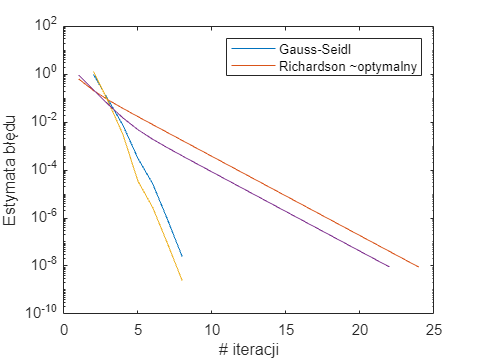

%Czyszczenie
clear all;clc;

% Najpierw zdefiniujmy przykładowy ukłąd równań:
A=wilkinson(5)+10*eye(5);
b=sum(A,2);


%Przyjęcie parametrów dla algorytmu iteracyjengo 
    
%-> punkt startowy - losowy
x0=rand(numel(b),1);
    
%-> wymagana dokłaność
delta0 = 1e-8;
    
%-> maksymalna ilość iteracji
i_max = 50;
    
%Implementacja metody Gaussa-Seidla
GaussItr=0;     %licznik iteracji 
x=x0;
n=size(x,1);
err = [Inf];%wektor błędów do rysowania

while ( (err(end)>=delta0) & (GaussItr<i_max))
    x_old=x;
    
    for i=1:n
        
        sigma=0;
        
        for j=1:i-1
                sigma=sigma+A(i,j)*x(j);
        end
        
        for j=i+1:n
                sigma=sigma+A(i,j)*x_old(j);
        end
        
        x(i)=(1/A(i,i))*(b(i)-sigma);
    end
    
    GaussItr=GaussItr+1;
    normVal=norm(x_old-x);
    err=[err;normVal];
end
    
%Rysowanie błędu
%hold off;

semilogy(err);xlabel("# iteracji");ylabel("Estymata błędu");
hold on;

% Roziąznaie metodą Richardsona
% Dokonajmy teraz rozkłądu macierzy A wg schematu metody Richardsona
% uzyskując macierz M i wektor w

p=0.06;
M=eye(size(A,1))-p*A;
w=p*b;
    
%Implementacja metody Richardsona
i=1;     %licznik iteracji 
error=Inf;
x_old=x0;
x=x_old; %wektor rozwiązań w kolejnych iteracjach;
n=i;     %wektor numerów iteracji do rysowania
err = [];%wektor błędów do rysowania
while( (error>=delta0) & (i<i_max))
    x_new = M*x(:,end)+w;
    error = norm(x_new-x_old);  %obliczenie esymaty błędu
    x_old=x_new;
    x=[x x_new]; 
        
    err=[err error];  
    n=[n i];i = i+1;
        
end
    
%Rysowanie błędu
%hold off;
semilogy(err);legend("Gauss-Seidl", "Richardson ~optymalny");